syms s;
[n1, d1] = deal(s-1, s^2+3*s+1);
[n2, d2] = deal(10*s^3-3*s^2+13*s-2, 10*s^3+8*s^2-5*s+4);
[num, dem] = deal(n2,d2);
%K=10;
%K = 4.15
K = 6

K = 6

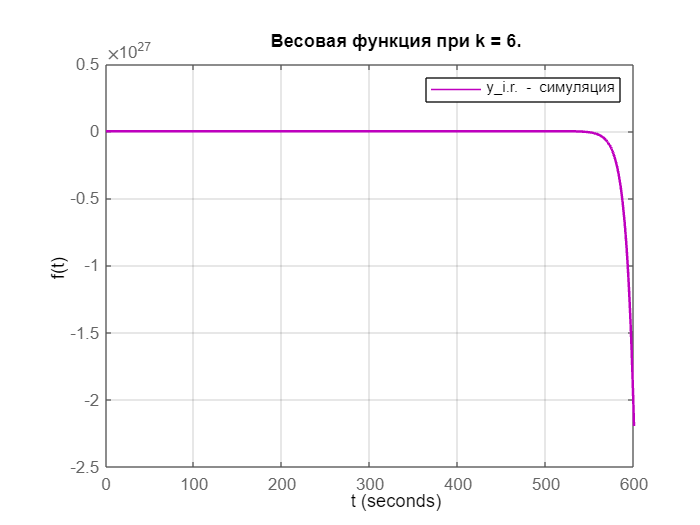

tau = 10000;
num = K*num;


%{
p_open = solve(dem);
p_close = solve(num+dem);
clf reset;
hold on;
%figure('Position', [1000 0 800 450])
x_open = real(p_open);
x_close = real(p_close);
y_open = imag(p_open);
y_close = imag(p_close);
x_min = double(min(min(cat(2, x_open, x_close)))-0.2);
x_max = double (max(max(cat(2, x_open, x_close)))+0.2);
y_min = double(min(min(cat(2, y_open, y_close)))-0.2);
y_max = double (max(max(cat(2, y_open, y_close)))+0.2);

plot([x_min x_max], [0 0], 'k--')
plot([0 0], [y_min y_max], 'k--')

plot(x_open, y_open, "*", Color='red', DisplayName='Разомкнутая система', LineWidth=1.5)
plot(x_close, y_close, "o", Color='blue', DisplayName='Замкнутая система', LineWidth=1.5)
%legend('', '', 'Разомкнутая система', 'Замкнутая система')
xlim([x_min x_max])
ylim([y_min y_max])
title('Изображение полюсов систем при k = 15')
xlabel("Re")
ylabel("Im")
hold off;


solve(dem);
solve(num+dem);

n_coeffs = sym2poly(num);
d_coeffs =  sym2poly(dem);

F = tf(n_coeffs, d_coeffs);

clf reset;
figure('Position', [1000 0 800 450])
[re,im,wout] = nyquist(F);
nyquist(F, 'g-')
%grid on
%xlim([-5 * 10 5 * 10])
%ylim([-3 3])
title("Годограф Найквиста для замкнутой системы")
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2);
%}



n_coeffs = sym2poly(num);
d_coeffs =  sym2poly(num +dem);

sys_i = tf(n_coeffs, d_coeffs);

%sys_s = tf(num_s, den_s);


impulse(sys_i, 'm')
legend('y_{i.r.} - симуляция')
title('Весовая функция при k = 6.')
grid()
ylabel("f(t)")
xlabel('t')
%xlim([0 5])
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1.5);
hold off

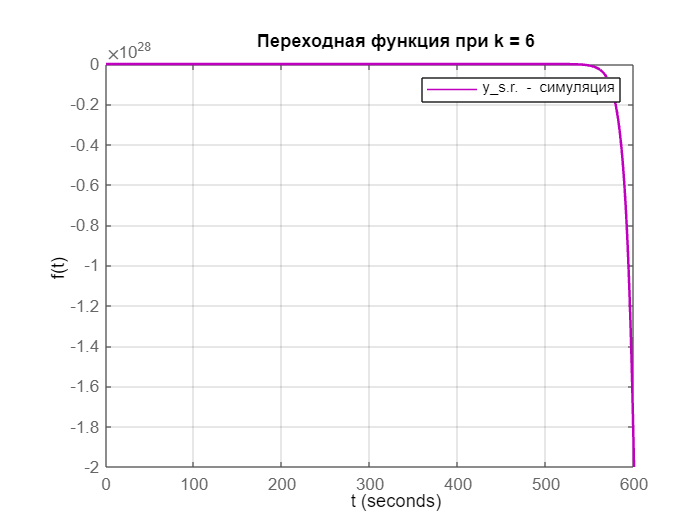




step(sys_i, 'm')
legend('y_{s.r.} - симуляция')
title('Переходная функция при k = 6')
grid()
ylabel("f(t)")
xlabel('t')
%xlim([0 5])
%ylim([0 15])
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 1.5);
hold off


%}

%{
figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'АФЧХ'
ops.Title.FontSize = 15
ops.XLabel.FontSize = 12
ops.YLabel.FontSize = 12
ops.FreqScale = 'Linear';
   
h = bodeplot(sys_i, 'c', ops)
grid on;

%}
%{
w = linspace(0, 1000)

figure('Position', [1000 0 800 450])

plot(w, phi1, 'LineWidth', 1.5,'DisplayName', 'ФЧХ')
%semilogx(w, phi)
title('Фазово-частотная характеристика')
legend()
ylabel('φ, degrees')
xlabel('ω, rad / s')
%ylim([-200 20])
grid("on")
%}
